# Data Visualization: Scatter Plots

#### by Rodolfo Muñoz

Similar to the previous example, we're going to load the data from our spreadsheet into a table.

clear variables; close all; clc;
[filename,path] = uigetfile('*.xls;*.xls');
colors = [0.4 0.5 1; 0 0 0];

tabds = datastore([path filename],'Type',"spreadsheet");

tabds.ReadSize = 'sheet';
preview(tabds)

ans = 8×21 table
    RowID         OrderID           OrderDate      ShipDate           ShipMode          CustomerID        CustomerName           Segment            Country                City                State         PostalCode     Region           ProductID              Category           Sub_Category                                  ProductName                                 Sales     Quantity    Discount    Profit 
    _____    __________________    ___________    ___________    __________________    ____________    __

For this analysis we'll look over the sales values so we'll retrieve only a handful of columns from the table.

tabds.SelectedVariableNames = {'OrderDate','CustomerID','Segment','Category','Sales','Quantity','Profit'};
tab = read(tabds);

## Profit vs cost

Bar plots to check quickly how the margin of profit relates to the total effort (costs involved) made each year.

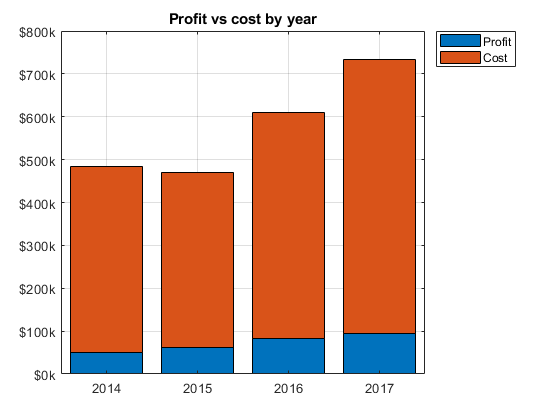

figure;
sum_y = groupsummary(tab(:,{'OrderDate','Sales','Profit'}),{'OrderDate'},["year"],'sum');
bar(sum_y.year_OrderDate,[sum_y.sum_Profit,sum_y.sum_Sales-sum_y.sum_Profit]/1e3,['stacked']);
ytickformat('$%.0fk')
legend({'Profit','Cost'},'Location','northeastoutside')
title('Profit vs cost by year')
grid on

% fig2pdf('ProfitVsCost')

While in the graph the profit doesn't seem to go up as much as the sales in the last 4 years, we can check that actually the company's has become more efficient and managed to improve its margin of profit:

sales_increase_percent = (sum_y.sum_Sales(end)/sum_y.sum_Sales(1)-1)*100

sales_increase_percent = 51.4133

profit_increase_percent = (sum_y.sum_Profit(end)/sum_y.sum_Profit(1)-1)*100

profit_increase_percent = 88.5987

profit_margin = sum_y.sum_Profit./sum_y.sum_Sales

profit_margin =     0.1023
    0.1310
    0.1343
    0.1274


margin_increase_percent = (profit_margin(end)/profit_margin(1)-1)*100

margin_increase_percent = 24.5588

## BoxPlots

Finally, we can see these average ticket filtered by each customer type to check if they have different behaviours: 

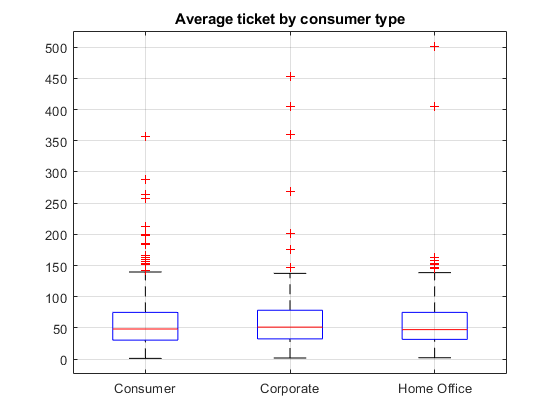

tab_aux = tab(:,{'CustomerID','Segment','Sales','Quantity'});
stats = grpstats(tab_aux(:,{'CustomerID','Sales','Quantity'}),{'CustomerID'},{'mean','sum'});

figure;
boxplot(stats.sum_Sales./stats.sum_Quantity,groups)
xticklabels(ID)
title('Average ticket by consumer type')
grid on;

By looking at the boxplot, we can say that in regards to the sales each customer type behaves very similarly with only ourliers as the main difference.